#### Задача 4.1

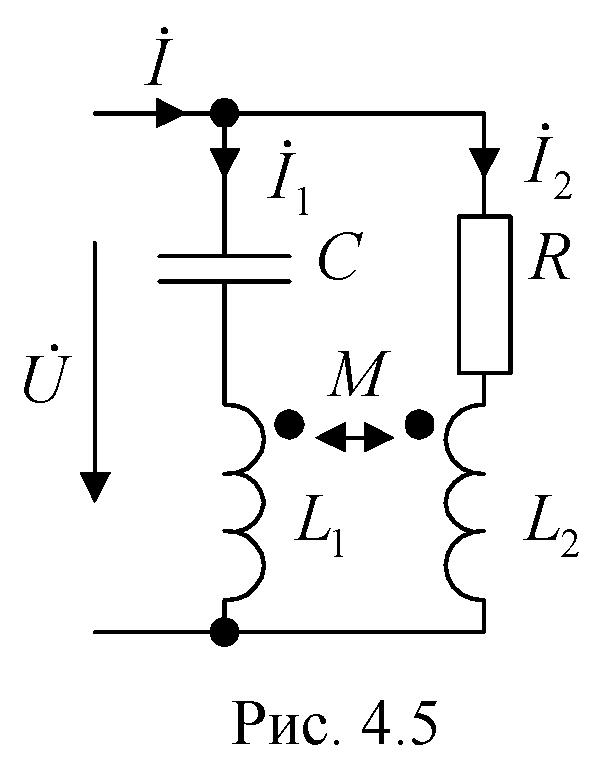

% U = 100 В
% R = 100 Ом
% X_L1 = X_L2 = X_C = 100 Ом
% X_M = 0.5*X_L1

clear
format short
digits(3)
syms I I1 I2 Z1 Z2 X_M I1 I2 U
eq1=I==I1+I2

$$eq1 = \text{I}=I_{1}+I_{2}$$

eq2=Z1*I1+j*X_M*I2==U

$$eq2 = I_{1}\,Z_{1}+I_{2}\,X_{M}\,\mathrm{i}=U$$

eq3=j*X_M*I1+Z2*I2==U

$$eq3 = I_{2}\,Z_{2}+I_{1}\,X_{M}\,\mathrm{i}=U$$

slv=solve([eq2,eq3],[I1 I2])

slv = struct with fields:
    I1: [1×1 sym]
    I2: [1×1 sym]


I1=slv.I1, I2=slv.I2

$$I1 = \frac{U\,\left(X_{M}+Z_{2}\,\mathrm{i}\right)}{{X_{M}}^{2}\,\mathrm{i}+Z_{1}\,Z_{2}\,\mathrm{i}}$$

$$I2 = -\frac{U\,\left(-Z_{1}+X_{M}\,\mathrm{i}\right)\,\mathrm{i}}{{X_{M}}^{2}\,\mathrm{i}+Z_{1}\,Z_{2}\,\mathrm{i}}$$

U=100;R=100;X_L1=100;X_L2=100;X_C=100;X_M=X_L1;
Z1=vpa(-j*X_C+j*X_L1)

$$Z1 = 0.0$$

Z2=vpa(R+j*X_L2)

$$Z2 = 100.0+100.0\,\mathrm{i}$$

X_M=vpa(0.5*X_L1)

$$X\_M = 50.0$$

I1=vpa((U*(X_M + Z2*1i))/(X_M^2*1i + Z1*Z2*1i)), Ip1=vpa([abs(I1),angle(I1)*180/pi])

$$I1 = 4.0+2.0\,\mathrm{i}$$

$$Ip1 = \left(\begin{array}{cc} 4.47 & 26.6 \end{array}\right)$$

I2=vpa(-(U*(X_M*1i - Z1)*1i)/(X_M^2*1i + Z1*Z2*1i)), Ip2=vpa([abs(I2),angle(I2)*180/pi])

$$I2 = -2.0\,\mathrm{i}$$

$$Ip2 = \left(\begin{array}{cc} 2.0 & -90.0 \end{array}\right)$$

I=vpa(I1+I2), Ip=vpa([abs(I),angle(I)*180/pi])

$$I = 4.0$$

$$Ip = \left(\begin{array}{cc} 4.0 & 0 \end{array}\right)$$

U_L1=vpa(j*X_L1*I1+j*X_M*I2), Up_L1=vpa([abs(U_L1),angle(U_L1)*180/pi])

$$U\_L1 = -100.0+400.0\,\mathrm{i}$$

$$Up\_L1 = \left(\begin{array}{cc} 412.0 & 104.0 \end{array}\right)$$

U_L2=vpa(j*X_L2*I2+j*X_M*I1), Up_L1=vpa([abs(U_L1),angle(U_L1)*180/pi])

$$U\_L2 = 100.0+200.0\,\mathrm{i}$$

$$Up\_L1 = \left(\begin{array}{cc} 412.0 & 104.0 \end{array}\right)$$

U_C=vpa(-j*X_C*I1), Up_C=vpa([abs(U_C),angle(U_C)*180/pi])

$$U\_C = 200.0-400.0\,\mathrm{i}$$

$$Up\_C = \left(\begin{array}{cc} 447.0 & -63.4 \end{array}\right)$$

U_R=vpa(R*I2), Up_R=vpa([abs(U_R),angle(U_R)*180/pi])

$$U\_R = -200.0\,\mathrm{i}$$

$$Up\_R = \left(\begin{array}{cc} 200.0 & -90.0 \end{array}\right)$$

U_L1+U_C,U_L2+U_R

$$ans = 100.0$$

$$ans = 100.0$$

S_1M=j*X_M*I2*I1'

$$S\_1M = 400.0-200.0\,\mathrm{i}$$

S_2M=j*X_M*I1*I2'

$$S\_2M = -400.0-200.0\,\mathrm{i}$$

P_1M=real(S_1M)

$$P\_1M = 400.0$$

P_2M=real(S_2M)

$$P\_2M = -400.0$$

phi=0

phi = 0

P_ist=U*I*cos(phi)

$$P\_ist = 400.0$$

P_R=Ip2(1)^2*R

$$P\_R = 400.0$$

Векторные диаграммы токов и напряжений приведены на рис. 4.6.

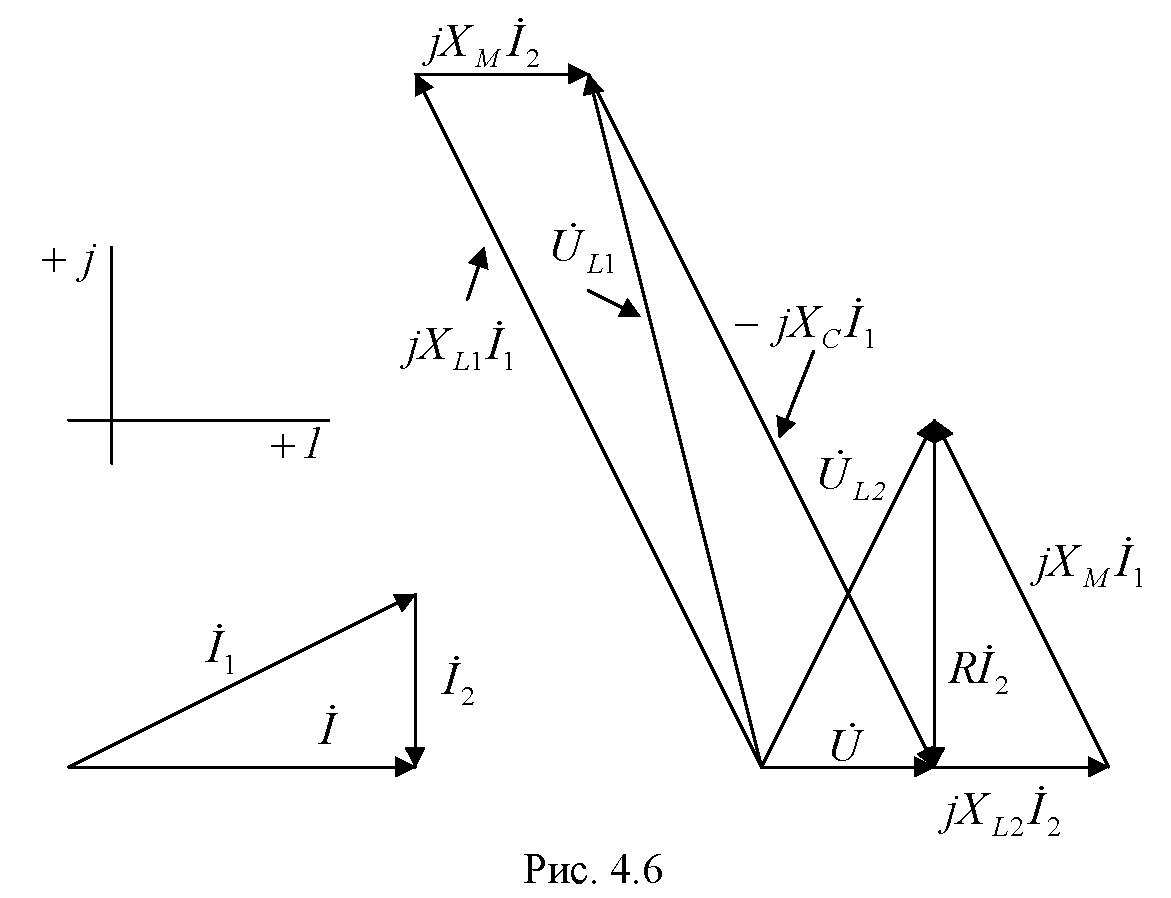

На рис.4.7. показана схема включения ваттметров.